clc;
clear;
rng(5,"simdTwister")
range = 100;
n = 9;
dro(1:n) = struct('pos',[0;0],'end',[0;0]);
rsqrd = sqrt(range^2 + range^2)

rsqrd = 141.4214

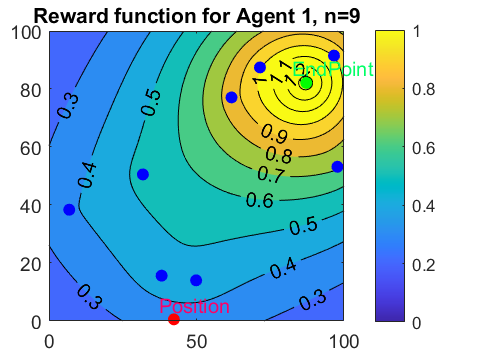

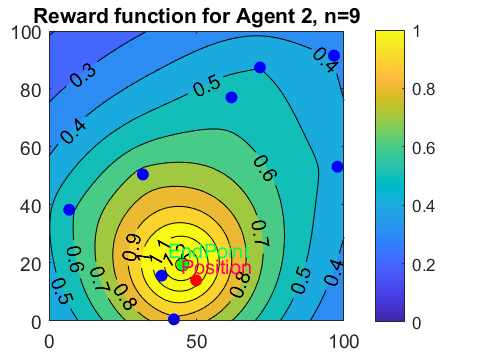

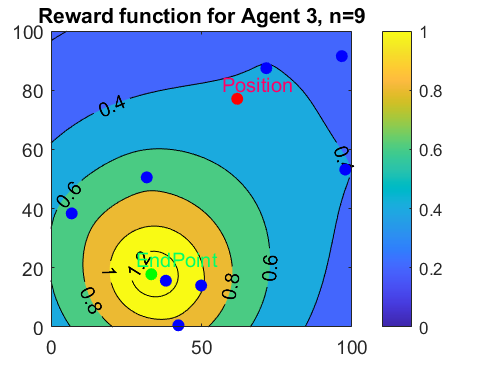

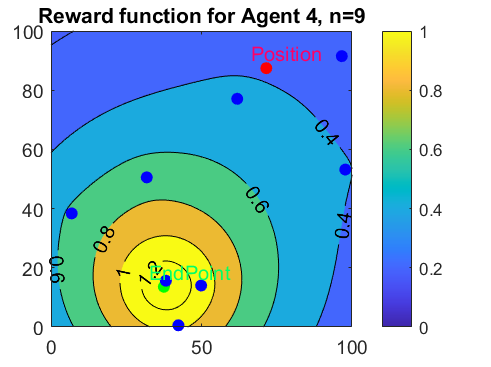

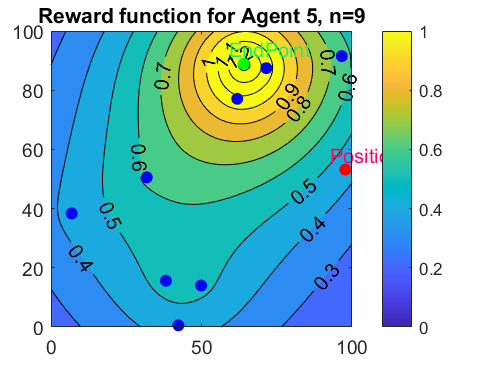

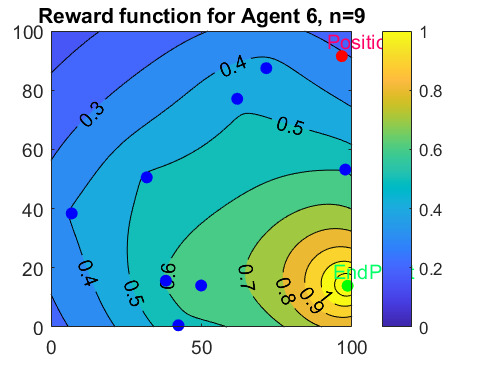

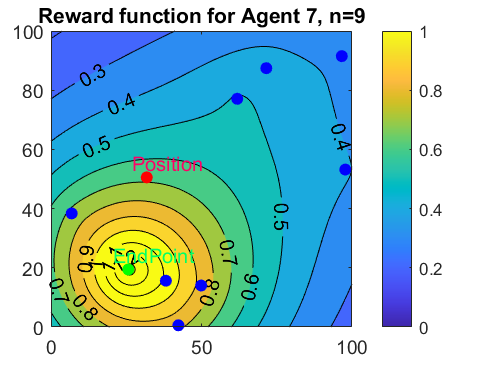

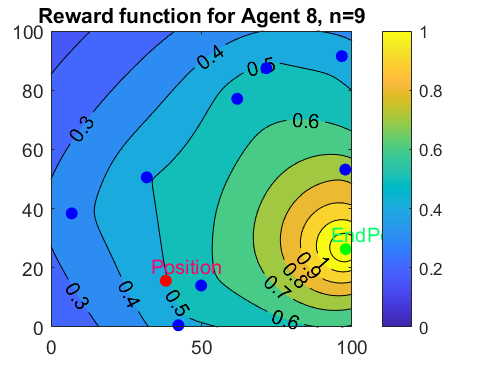

for i = 1:n
    dro(i).pos = rand(2,1)*range;
    dro(i).end = rand(2,1)*range;
    
end

    kd = -log(0.5)/(0.2*rsqrd);
    kdn = -log(0.05)/(0.2*rsqrd);
    ke = -log(0.1)/(0.5*rsqrd);

for i = 1:n
    flo = 1:n;
    flo(i)= [];
    x = linspace(0,range,1000);
    y = linspace(0,range,1000);

    [X,Y] = meshgrid(x,y);



    rend = exp(-ke*sqrt(((dro(i).end(1,1)-X).^2 + (dro(i).end(2,1)-Y).^2)));
    rdro= zeros(1000,1000);
    for ii = flo
        rdro = rdro + exp(-kd*sqrt(((dro(ii).pos(1,1)-X).^2 + (dro(ii).pos(2,1)-Y).^2)));
    end
    rT = rdro/(n-1) + rend;
    
    figure
    Rplot(i) = figure('Name','ContourPlotForDrone ' + string(i));
    
    contourf(X,Y,rT,'ShowText','on','LineWidth',0.1)
    colorbar
    clim([0 1])
    hold on
    scatter(dro(i).pos(1,1),dro(i).pos(2,1),'red',"filled",'o')
    scatter(dro(i).end(1,1),dro(i).end(2,1),'green',"filled",'o')

    for ii = flo
        
        scatter(dro(ii).pos(1,1),dro(ii).pos(2,1),'blue',"filled",'o')
    end
    hold off
 
    text(dro(i).end(1,1)-0.05*range,dro(i).end(2,1)+0.05*range,'EndPoint','Color',[0 1 0.4])
    text(dro(i).pos(1,1)-0.05*range,dro(i).pos(2,1)+0.05*range,'Position','Color',[1 0 0.4])
    title('Reward function for Agent '+string(i)+', n='+string(n))
    saveas(Rplot(i),'RewardFunction'+string(i) +'.jpg')   

xlim([0 100])
ylim([0 100])
end

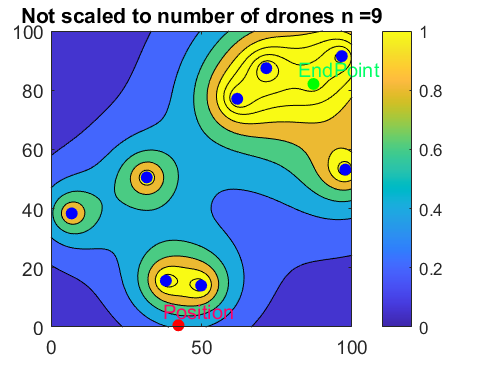



for i = 1:1
    flo = 1:n;
    flo(i)= [];
    x = linspace(0,range,1000);
    y = linspace(0,range,1000);

    [X,Y] = meshgrid(x,y);



    rend = exp(-ke*sqrt(((dro(i).end(1,1)-X).^2 + (dro(i).end(2,1)-Y).^2)));
    rdro= zeros(1000,1000);
    for ii = flo
        rdro = rdro + exp(-kdn*sqrt(((dro(ii).pos(1,1)-X).^2 + (dro(ii).pos(2,1)-Y).^2)));
    end
    rT = rdro + rend;
    
    figure
    Rplot(i) = figure('Name','ContourPlotForDrone ' + string(i));
    
    contourf(X,Y,rT,'ShowText','off','LineWidth',0.1)
    colorbar
    clim([0 1])
    hold on
    scatter(dro(i).pos(1,1),dro(i).pos(2,1),'red',"filled",'o')
    scatter(dro(i).end(1,1),dro(i).end(2,1),'green',"filled",'o')

    for ii = flo
        
        scatter(dro(ii).pos(1,1),dro(ii).pos(2,1),'blue',"filled",'o')
    end
    hold off
 
    text(dro(i).end(1,1)-0.05*range,dro(i).end(2,1)+0.05*range,'EndPoint','Color',[0 1 0.4])
    text(dro(i).pos(1,1)-0.05*range,dro(i).pos(2,1)+0.05*range,'Position','Color',[1 0 0.4])
    title('Not scaled to number of drones n ='+string(n))
    saveas(Rplot(i),'RewardFunctionNotscaled'+string(n) +'.jpg')   
end